# Linear (Mixed) Effects Models for Statistical Analysis

*Bart Krekelberg - Last Update Jan 2023.*

ANOVA type analyses typically lead to binary statements such as "there was a significant effect of drug X on learning (p=0.001)", or "there was no significant effect of age (p>0.1)".  In fact, without at least one such significant effect it is difficult to publish a paper. This is bad for progress, as a well-designed experiment without significant effects can be as informative as one with significant effects.  Moreover, most null-hypotheses are thoroughly uninteresting. In the first example, for instance, the ANOVA approach rejected the null hypothesis that there was no effect of the drug. But is it interesting to reject this null hypothesis? Is it even a-priori possible that there is really no effect? The effect of a given dose could be small, even too small to measure reliably, but really zero-effect? In most neuroscience research we're much more interested in assessing how big an effect is. Is it big enough to be an important aspect of how the brain works? Hypothesis testing has its uses (for instance, admitting a drug to the market requires a binary decision : yes/no, and a strong hypothesis test can be useful to make that decision), but in most cases, estimation, not hypothesis testing is what we actually want.

## Don't hypothesize, estimate!

Linear (mixed) models  lend themselves well for this estimation purpose as they emphasize that statistical analysis is equivalent to (linear) model fitting; you are trying to describe a complex data set with a few linear relationships, and you are interested in finding out whether these relationships are strong and reliable. In other words, the goal is to *quantify* (model) relationships, rather than making a binary decision whether there is a relationship or not.  

Let's start with a simple example. We recorded neural activity (mean firing rate) after applying three levels of transcranial current in two animals. This is another case where the null-hypothesis is plain silly; given enough current, an effect of the current on neural activity is guaranteed. The question of interest is how strong the effect is at low doses that are tolerable to the subject.

% Setup independent variables to generate fake data
rng(1230,'twister'); % Keep random numbers repeatable between runs
currentDose     = [0.5 1 2]; % mA
nrDoses         = numel(currentDose);
nrAnimals       = 2;
nrNeurons = 10;

meanRate = [3 5 8];
rate = repmat(meanRate,[nrAnimals*nrNeurons 1]);
rate = rate(:) +randn([numel(rate) 1]);
animal    = repmat((1:nrAnimals)',[nrNeurons nrDoses ]);
animal     = categorical(animal(:));
dose    = repmat(currentDose,[nrNeurons*nrAnimals 1]);
dose = dose(:);
T=table(rate,animal,dose);

Visualize the raw data

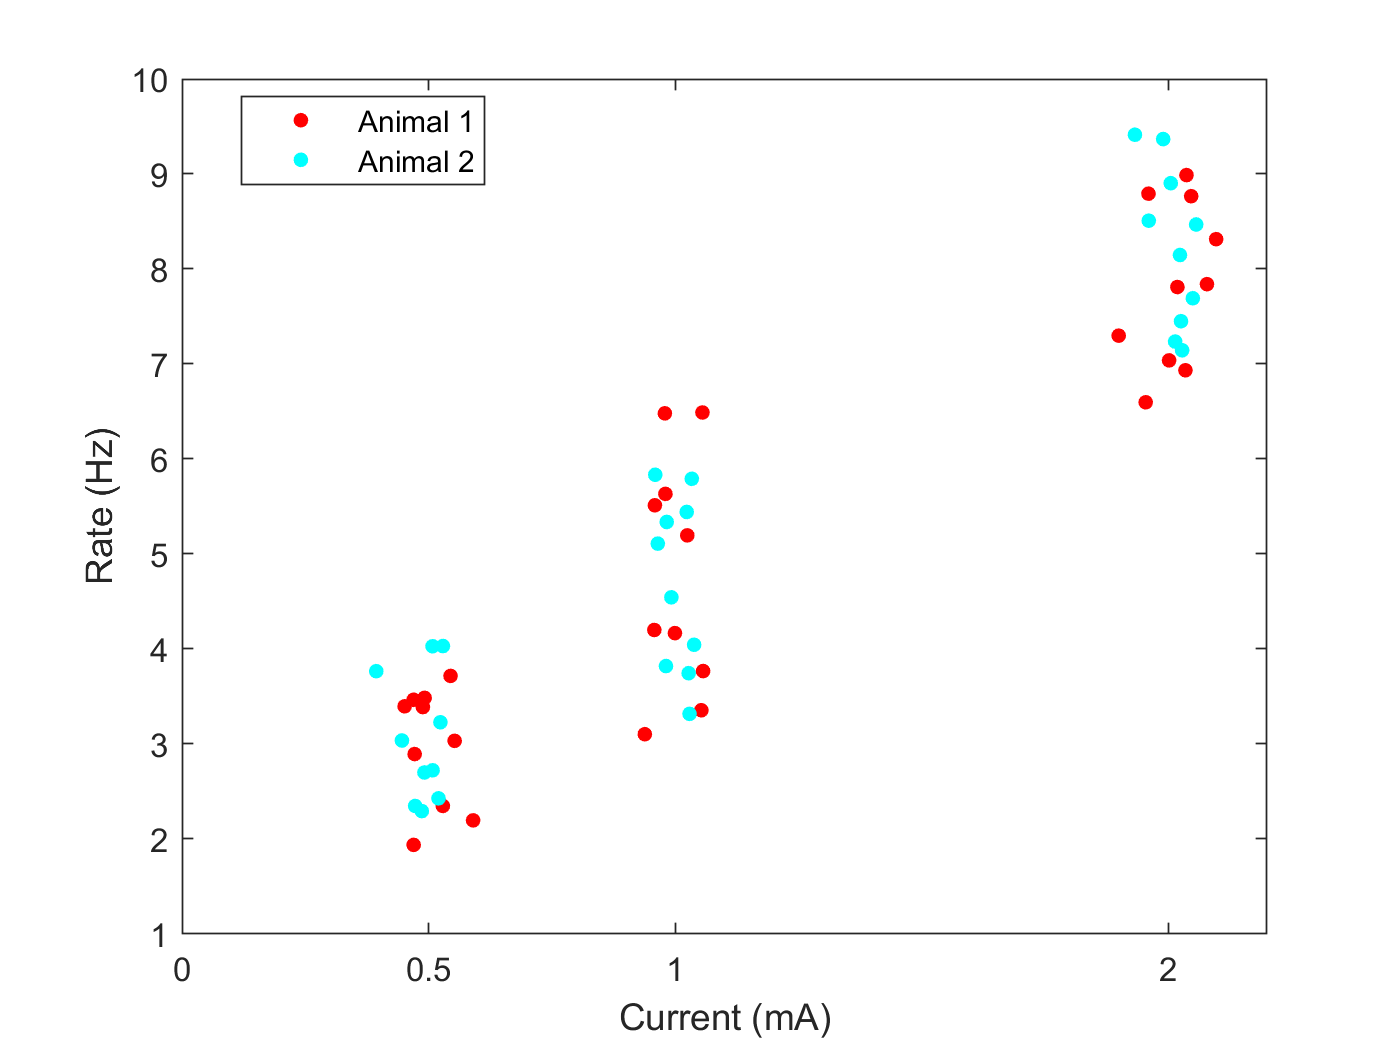

figure;clf;
horizontalJitter = 0.05*randn([height(T) 1]);
gscatter(T.dose+horizontalJitter,T.rate,T.animal);
xlabel 'Current (mA)'
ax = gca;
ax.XTick = [0 currentDose];
ax.XLim = [0 2.2];
ylabel 'Rate (Hz)'
legend('Animal 1','Animal 2')

The graph suggests that a linear model is reasonable. Mathematically, this model would be expressed as: $rate = constant + slope*dose + residuals$  or $rate = \beta_0 + \beta_1*dose + \epsilon
$, using the convention that $\beta$ refers to a parameter in a linear model. 

In other words, our hypothesis is that the rate is linearly related to the dose (the $slope/\beta_1$ parameter will capture the size of that effect), plus some constant ($\beta_0
$, will capture that effect). Anyhing that cannot be captured by this relationship is considered "residual noise" ($\epsilon$). 

Given some general assumptions (the same as those underlying traditional ANOVA; we'll discuss them below), these model parameters can be determined uniquely. Behind the scenes, Matlab's LinearModel class uses a maximum likelihood algorithm to estimate the parameter. You can be sure that the parameters returned by the fitting functions are the best ones (given the model and the data). 

Rather than the mathematical equations used above, the LinearModel uses so-called Wilkinson notation to specify a model. For instance:

`rate ~ 1 + dose`

In this notation ~  stands for 'depends on' and the `1` stands for the constant term. The  word `dose` instructs the LMM to fit a linear term for the dose.  You should not specify the residuals: all Linear Models assume that there will be residuals. (Note that LMM will also assume a constant term by default so the '1' can be left out as well. If you want to fit a model without a constant term you have to specify -1, which stands for "fit a model without a constant term").

Let's put this into code  (this wonderfully compact notation relies on the columns in `T` having the names `rate` and `dose`, which is why I like using Matlab tables with linear models):

lmm = fitlme(T,'rate~1+dose')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations              60
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rate ~ 1 + dose

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    156.23    162.51    -75.114          150.23  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF    pValue        Lower      Upper 
    {'(Intercept)'}         1.377      0.23173    5.9421    58    1.6975e-07    0.91313    1.8409
    {'dose'       }        3.3348      0.17517    19.037    58    1.2665e-26     2.9841    3.6854

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower      Upper
    {'Res Std'}        0.84617     0.70755    1.012


The `lmm `object contains the full linear model, based on the data in the table, and the Wilkinson formula.

The 'fixed effects coefficients' are the model parameters of interest. In this case, they are the `Intercept (`$\beta_0
$ ): the predicted firing rate when the dose is zero, and the effect of `dose (`$\beta_1$)`: `with each mA of current, the firing rate increases by this amount.

Note how the `lmm` output shows both the estimate of these fixed effects, and the `Lower` and `Upper` limits of their confidence intervals . For instance, for the parameter of interest, `dose`, we see that the estimate is 3.3. This means that for every mA increase in dose, the firing rate increases by 3.3 Hz. The Lower and Upper columns show the 95% confidence limits of the estimate. Therefore, given these data, the effect of the dose lies with 95% probability in the range 2.98 to 3.68 Hz/mA. That is the kind of quantification of an effect that should be the goal of a neuroscience experiment. More and more journals are requiring such quantification (i.e. an estimate and confidence limits see, for instance, this [article](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6709209/) and [editorial](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6709206/) in eNeuro).

Of course, it will be a while until we can forget about p-values for our papers, so, luckily, the `lmm` also gives you a p-value associated with the null-hypothesis that a fixed effect is zero. Here, only the fixed effect of `dose` is of interest and we see that the p-value is very small (consistent with the observation that zero is far outside the 95% confidence interval). We can extract all of these numbers from the `lmm` object (for its full set of properties, see` help LinearModel).`

The recommended way to report this finding in a paper would be something like this:

effectName = 'dose';
row = find(strcmp(effectName,lmm.CoefficientNames)); % Find the parm of interest
fprintf('The (fixed) effect of %s was %3.3f (CI: [%3.3f,%3.3f]) ', ...
    effectName,lmm.Coefficients.Estimate(row),lmm.Coefficients.Lower(row),lmm.Coefficients.Upper(row))

The (fixed) effect of dose was 3.335 (CI: [2.984,3.685]) 

And to report the ANOVA statistics:

alpha =0.05;
if lmm.anova.pValue(row)>alpha
    not='not';
else
    not = '';
end
fprintf('The (fixed) effect of %s was %s significantly different from zero: F(%d,%d) = %3.2f (p = %3.3g)', ...
    effectName,not,lmm.anova.DF1(row),lmm.anova.DF2(row),lmm.anova.FStat(row),lmm.anova.pValue(row))

The (fixed) effect of dose was  significantly different from zero: F(1,58) = 362.40 (p = 1.27e-26)

We can plot the linear model on top of the data to show how well it fits.

hold on;
%Use linear algebra to multiply the fixed effects with the dose values on
%the x-axis.
x = [ones(1,nrDoses);currentDose]

x =     1.0000    1.0000    1.0000
    0.5000    1.0000    2.0000


predicted = lmm.fixedEffects'*x

predicted =     3.0444    4.7118    8.0465


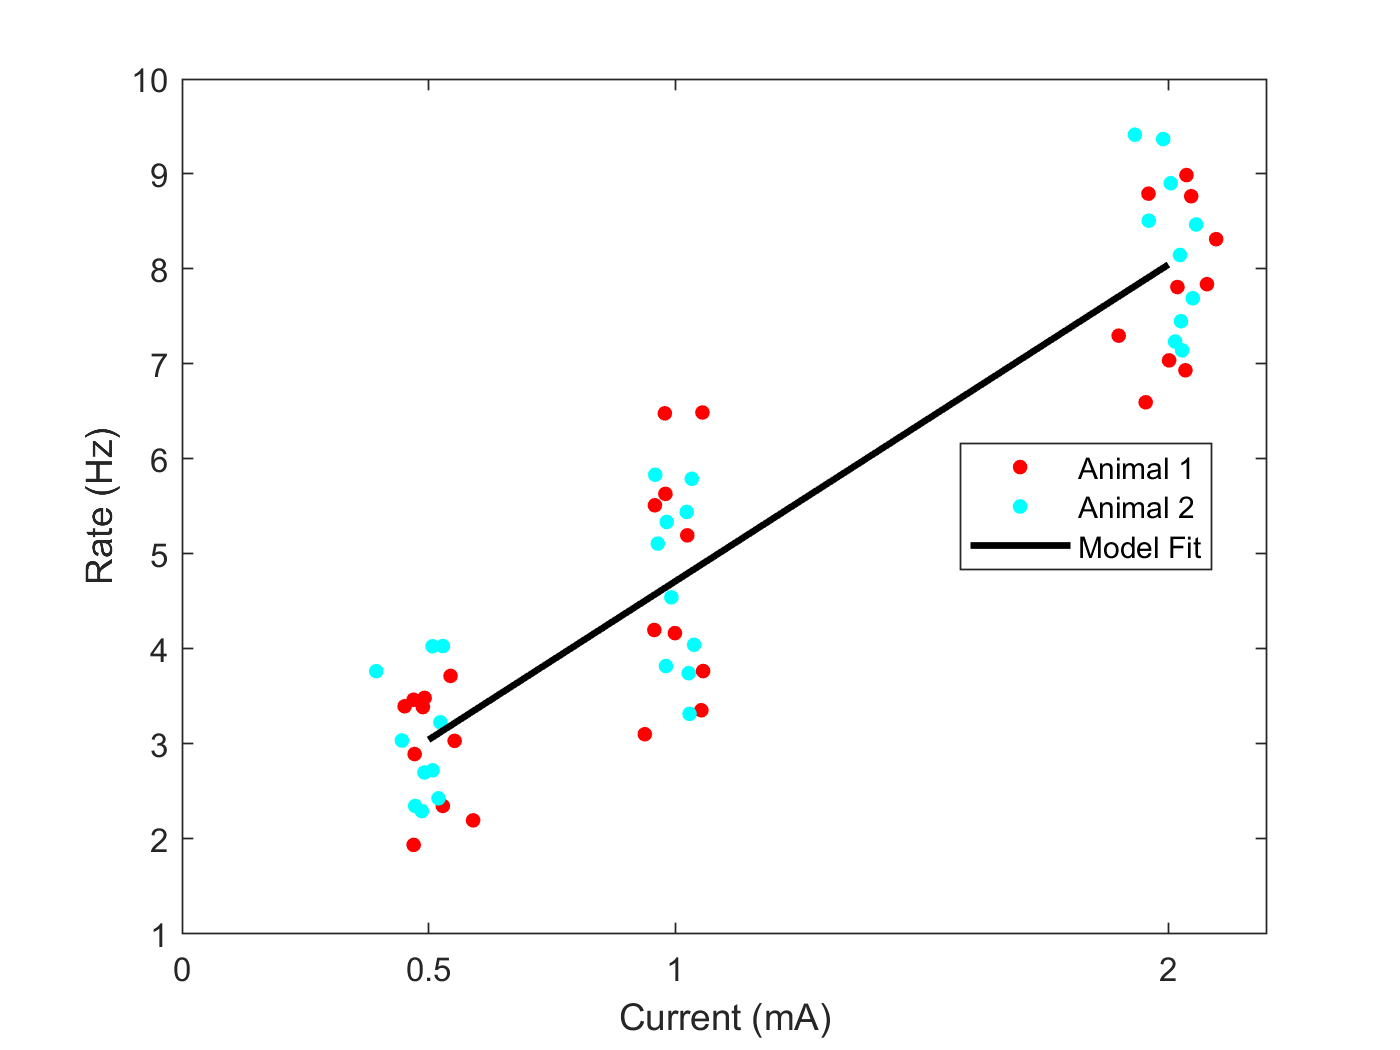

plot(currentDose,predicted,'k','LineWidth',2)
legend('Animal 1','Animal 2','Model Fit')

## Assumptions

Many of the assumptions needed for a linear model are the same as those for the use of an ANOVA. For instance, for an ANOVA it is often stated (somewhat incorrectly) that the data have to be normally distributed.  The linear model allows us to formulate this more correctly; the *residuals* of the model should be normally distributed with zero mean. This is something you should check with the `lmm` object, which has computed not only the best fitting parameters, but also the residuals (i.e. the mismatch of each measurement with the prediction of the model).

We can inspect the residuals graphically, for instance as a histogram or a quartile-quartile (q-q) plot:

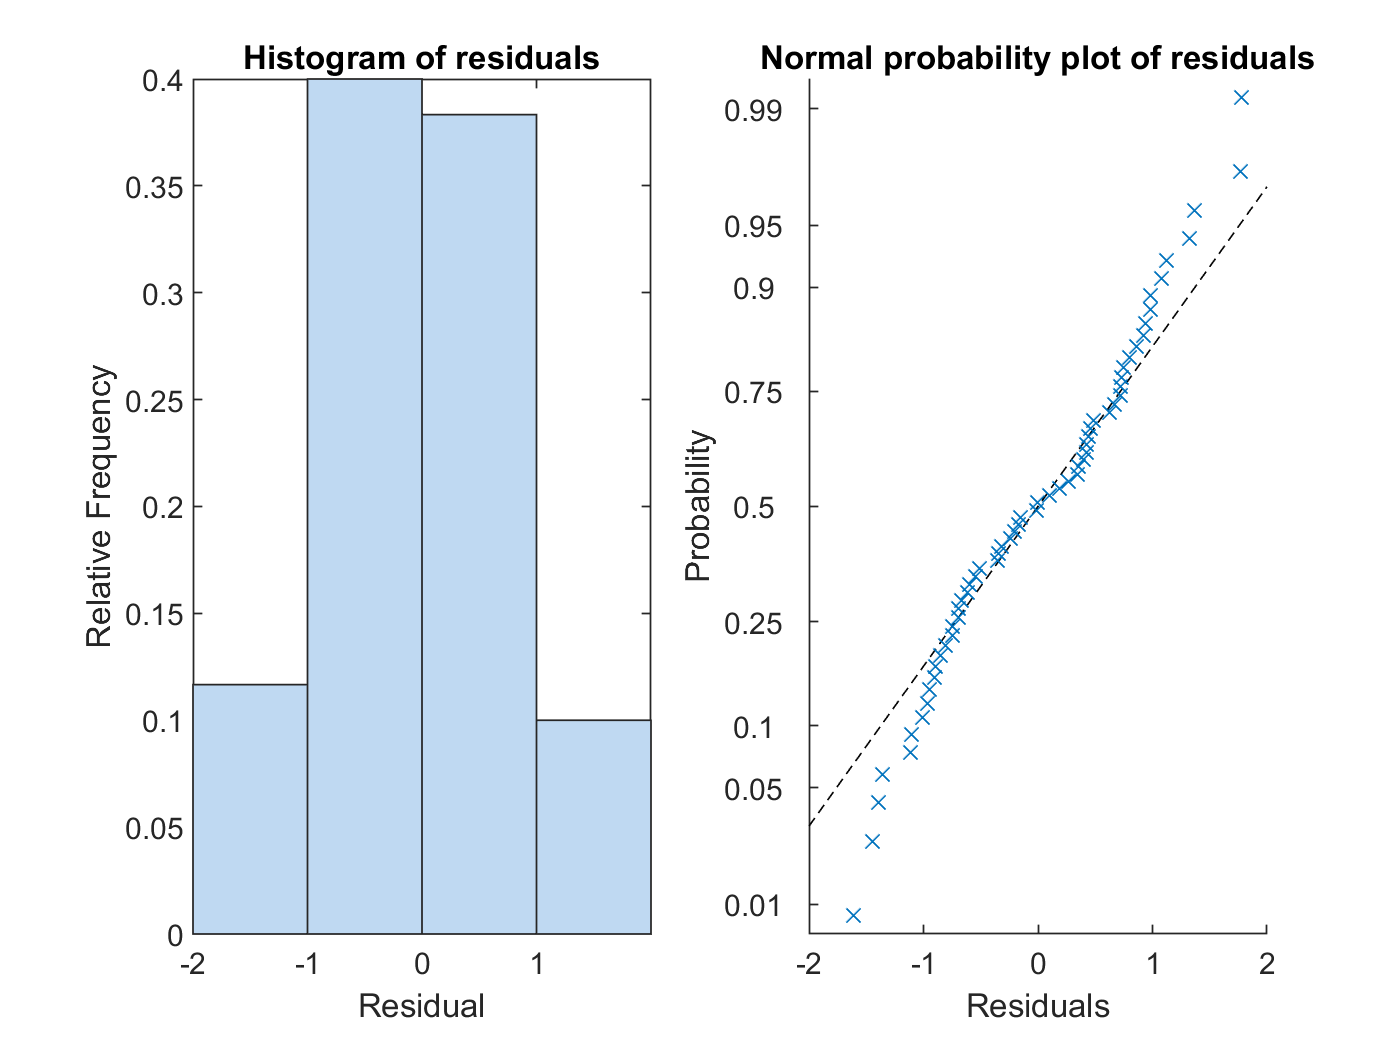

subplot(1,2,1)
plotResiduals(lmm,'Histogram')
xlabel 'Residual'
ylabel 'Relative Frequency'
subplot(1,2,2)
plotResiduals(lmm,'probability')

The left plot should  look like a normal distribution and in the right subplot the data points should lie along the dashed line. Especially for small sample sizes, you will always see some deviation (especially for the larger residuals). More deviations from the dashed line for negative than for positive residuals (asymmetry), or large deviations in the center of the plot are reasons to doubt normality.  

To assess normality quantitatively, first extract the residuals:

R = residuals(lmm); % The mismatch 

Then, create a normal distribution with zero mean and a standard deviation that matches the standard deviation of the residuals:

normal = makedist('norm','mu',0,'sigma',nanstd(R));

To test whether the actual residual distribution is significantly different from this normal distribution, we use the Kolmogorov-Smirnov test (which detects any difference between two distrubutions, not just a difference in mean or standard deviation)

[notNormal,p] = kstest(R,'cdf',normal)

notNormal = logical
   0


p = 0.6522

This tests the null-hypothesis that the data were different from a zero-mean normal distribution. In this case, that null-hypothesis could not be rejected (notNormal ==false) witha  p-value of 0.6. Hence, we conclude that the residuals were normal enough to use the linear model. (An example where a binary decision is needed, and a hypothesis test is useful). 

Another assumption in linear models is that the variance is the same for each level in a factor (homoscedasticity). We can visualize this::

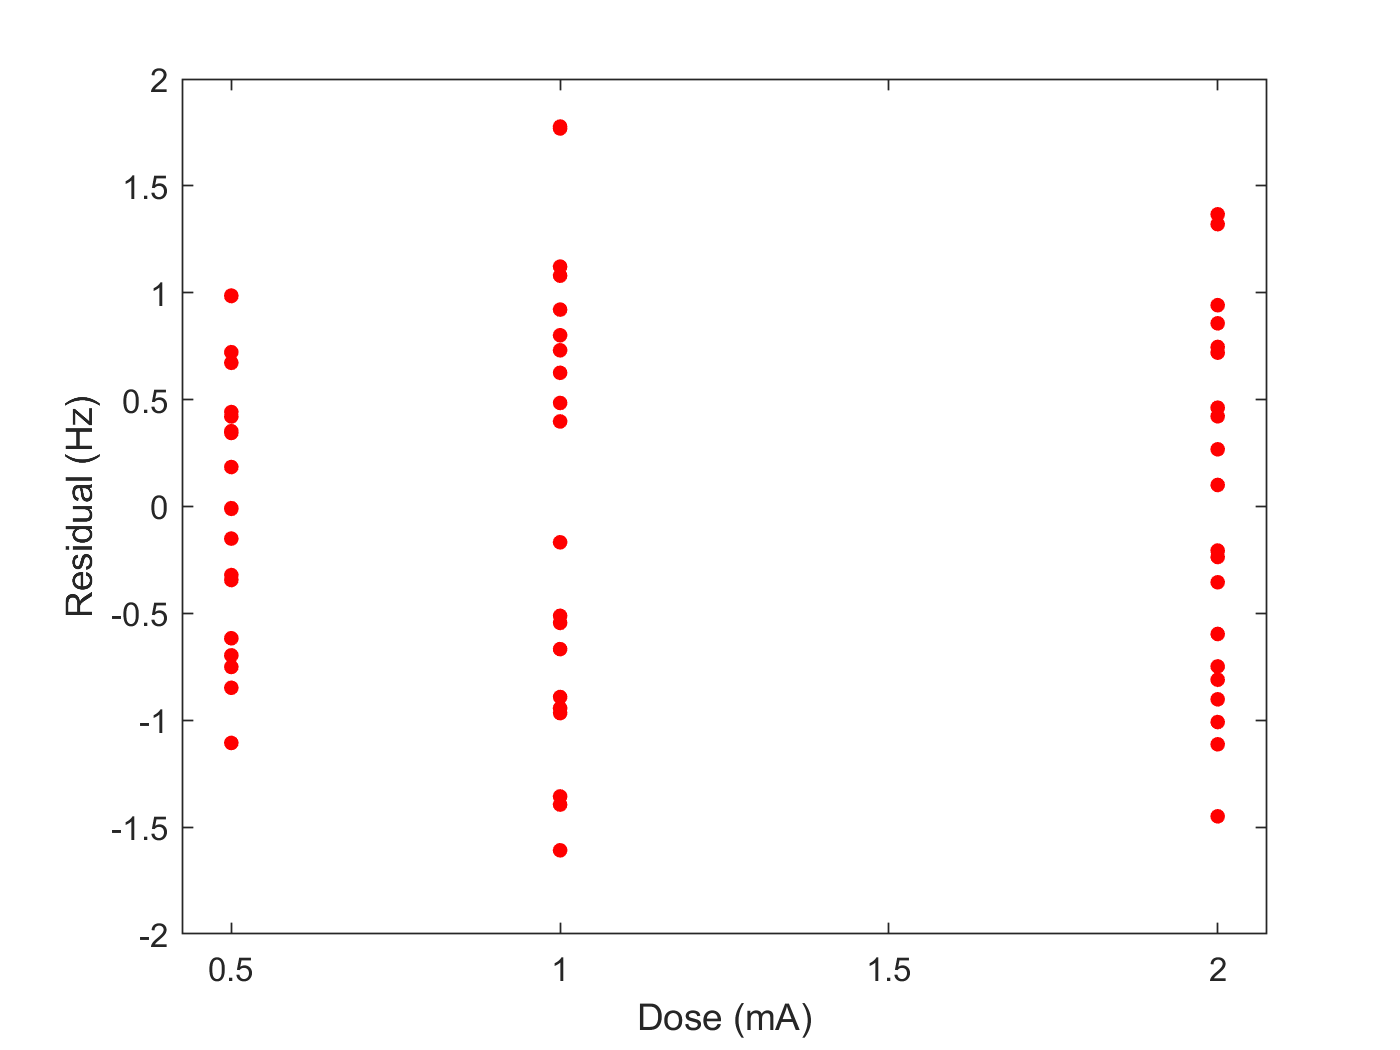

figure;
gscatter(T.dose,R)
xlabel 'Dose (mA)'
ylabel 'Residual (Hz)'

In this figure one would want to see similar distributions of the residuals along the y-axis (a violin plot could be helpful). By incorporating the residuals in the table, we can use the `groupsummary` function to quantify this:

fullT = addvars(T,R,'NewVariableNames','residual'); % Add R to the table
groupsummary(fullT,'dose','std','residual')

ans = 3×3 table
    dose    GroupCount    std_residual
    ____    __________    ____________

    0.5         20          0.63479   
      1         20           1.0644   
      2         20          0.85059   


While this gives you an idea of the homoscedasiticity, testing whether the requirement is met is not trivial, especially for small N. In general, linear model fits are quite robust against some heteroscedasticity. Hence, only if you see large differences in variance across the levels would you consider some alternative approach. Part II of the linear mixed models handouts discusses some common options, alternatively, the 'weights' parameter in the `fitlme` function call allows you to assign a  weight to each data point; if there is more variance in some conditions, then downweighting them (by 1/variance for instance), could help find a model that generates homoscedastic residuals.

### Why Normality and Homoscedasticity?

The reason for these assumptions is that they make it easy to translate observations (measurements) into probabilities, which can then be used to find the most probable model.

For instance,  if residuals are normally distributed, then each data point can be translated into a statement about the likelihood of observing that measurement given that the model is correct., 

Consider a model with residuals that follow a normal distribution with standard deviation $\sigma$. We can use the formula for the normal probability distribution to determine the likelihood of observing residual $r_i
$  (i.e. one data point):

$p(r_i) \approx exp(-r_i^2/\sigma^2)$.

If the variance of the residuals is the same for all values of the independent variable (homoscedasticity), then the same formula (same $\sigma
$) applies to all measurements. And, if each measurement is independent of the others, then the probability of observing all measurements (given the model) is the product of each of the individual probabilities. The product of exponentials can be rewritten as the exponential of the sum: 

$p(R) =p(r_1)*p(r_2)*...p(r_N)\approx exp (-(r_1^2 +r_2^2 + ... r_N^2)/\sigma^2)$, 

which we can rewrite as 

$p(R) \approx ~exp (-ss/\sigma^2)$              (Equation 1), 

with ss the sum of squared residuals: $ss = \sum_{i=1}^N r_i^2$

This shows that with the assumptions about the residuals, the likelihood of the model can be reduced to a relatively simple equation. Behind the scenes, the LinearModel class uses this to find the parameters that lead to the most likely model.

If residuals were not normally distributed then the relation between residuals and the likelihood of observing the data given the model would not be so straightfoward.. As a consequence, the algorithm could find a solution that is not the most likely given the data.  

If the residuals were heteroscedastic then the appropriate sigma would be different for some values of the independent variable. The optimization algorithm, however, assumes a single sigma, and in a heteroscedastic dataset this would give too much weight to some data points (those from independent variables with larger sigma).

## Categorical Variables

In the previous example, the effect of interest (dose) was numeric (the term 'continuous' is more common in statistics), and it was reasonable to hypothesize that the rate would change linearly with the applied current.  But there are many situations where the independent variable is not continous, but categorical. 

For instance, let's investigate firing rates in three cortical areas:

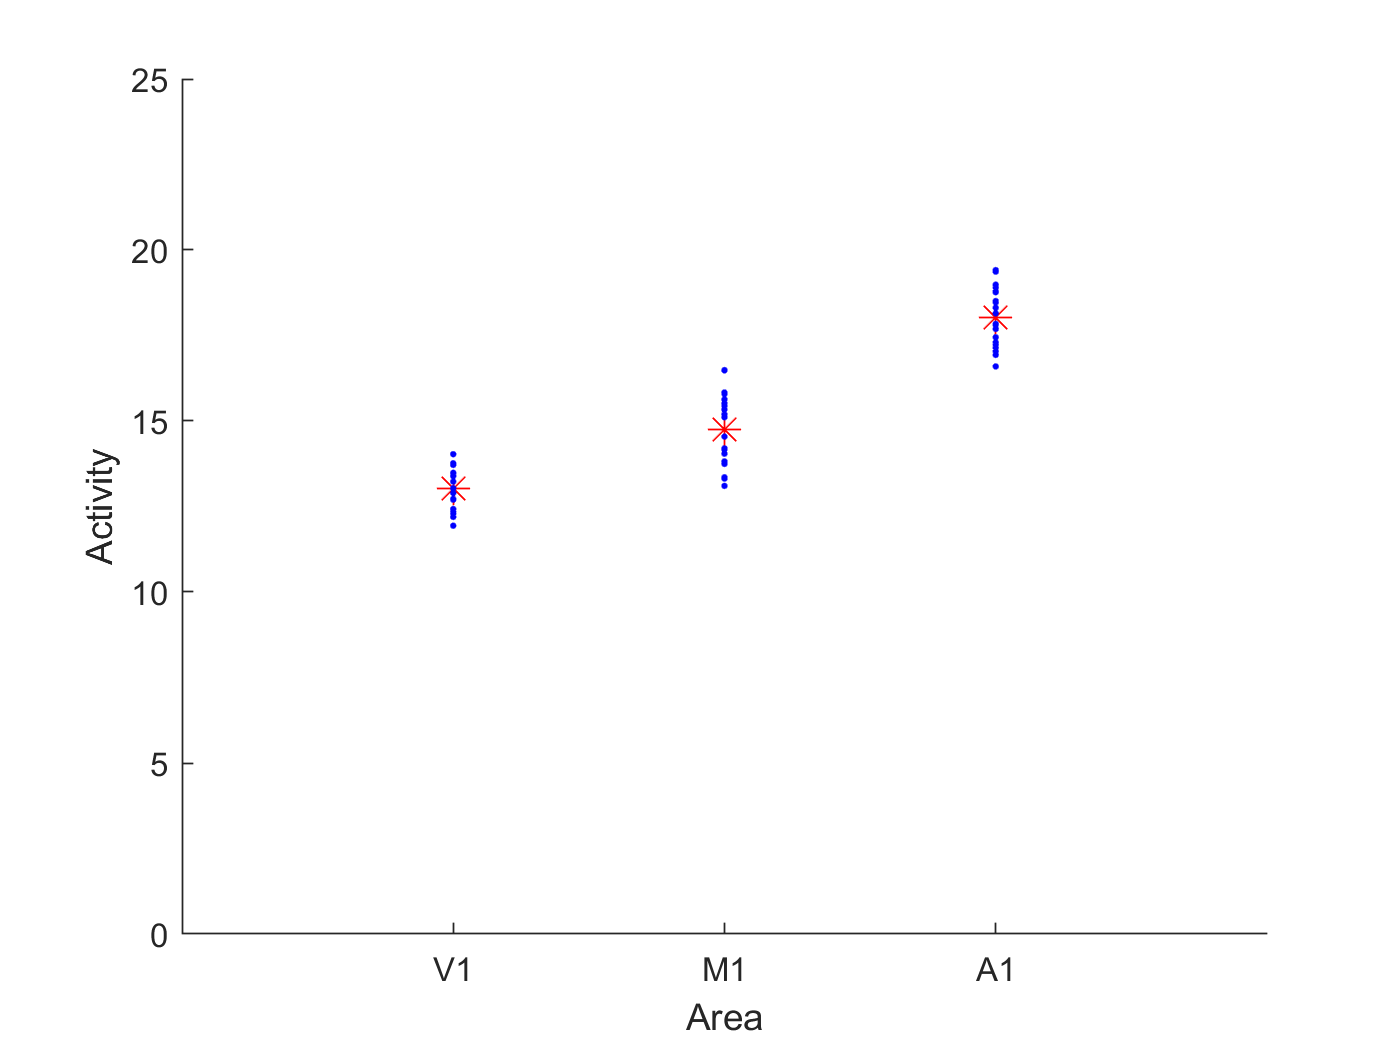

figure;
rng(1230,'twister'); % Keep random numbers repeatable between runs
nrNeurons = 20;
areaNames = {'V1','M1','A1'};
nrAreas = numel(areaNames);
areaActivity = 10+[3 5 8]; % Ground truth; the underlying means
measurementNoise = randn(nrNeurons,nrAreas);
activity = repmat(areaActivity,[nrNeurons 1]) +measurementNoise;
meanActivity = mean(activity);
figure(4);
clf;hold on
plot(1:nrAreas,meanActivity,'r*','MarkerSize',10);
plot(repmat(1:nrAreas,[nrNeurons 1]),activity,'b.');
xlabel ('Area')
ylabel ('Activity');
set(gca,'XTick',1:nrAreas,'XTickLabel',areaNames,...
                    'XLim',[0 nrAreas+1],'Ylim',[0 25]);                

When working with LMMs the Matlab table is really convenient, so let's put these data in a table. 

areaLabel = repmat(areaNames,[nrNeurons 1]);
T = table(activity(:),areaLabel(:),'VariableNames',{'rate','area'});

For these data, conceptualizing the analysis as a standard linear model ($rate =\beta_0 + \beta_1* area

$) makes little sense becasue `area `does not take on numeric values. Instead you can think of a model with one so-called indicator variable  (`isM1`) that takes on the value 1 if the area is M1, and 0 otherwise, and another indicator variable that takes on the value 1 if the area is A1 and zero otherwise (`isA1`). 


$$rate = \beta_0+\beta_1*isM1 + \beta_2*isA1
$$
 

The goal of the linear model fit will be to find the $\beta_0,\beta_1, \beta_2$ that best capture the data (in the least square sense, just as for continuous variables).  Think about what this model means. For instance, if we record from a neuron in V1, then both isM1 and isA1 will be 0, and the model states  $rate = \beta_0$. In other words, $\beta_0$ is the model-predicted firing rate for V1. For a neuron from A1, isM1 is 0, isA1 is 1 and we get $rate = \beta_0+ \beta_2
$. In other words, $\beta_2$ is the extra (positive or negative) firing rate observed in A1 compared to V1. 

In Wilkinson notation, the model specification is the sams for continuous or categorical variables ('rate ~ area'), or in Matlab code:

lmm = fitlme(T,'rate~area')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations              60
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rate ~ 1 + area

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    158.18    166.56    -75.091          150.18  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF    pValue        Lower     Upper 
    {'(Intercept)'}        13.022      0.18914    68.852    57    1.4379e-56    12.644    13.401
    {'area_M1'    }        1.7222      0.26748    6.4386    57    2.7257e-08    1.1866    2.2578
    {'area_A1'    }        5.0131      0.26748    18.742    57    4.8319e-26    4.4775    5.5487

Random effects covariance parameters (95% CIs):
Group: Error
    Name             

The `lmm` output shows that there are 3 fixed effects: one for the `Intercept,` one for `area_M1`, and one for `area_A1`, The latter two are the effects corresponding to indicator variables `isM1` (i.e. $\beta_1$) and `isA1 (i.e. `$\beta_2$). Note that Matlab auto-detects that the `area` variable in the Wilkinson formula is a categorical variable and therefore it uses the appropriate indicator variables internally. This works because `area` is a char. If you use a numeric value to represent areas (e.g. 1 for v1,2 for M1, 3 for A1) then Matlab has no way of telling that `area` is a categorical variable, and it would fit a model  assuming area is a continuous variable. Therefore,before you pass a table to `fitlme`, you should make sure that all variables that are categorical are indeed marked as such. You can convert numerical variables to categorical variables with the `categorical` funciton..

Now we can interpret the LMM output. The fixed-effect  (`Intercept`) corresponds to the (mean) predicted firing rate of V1 neurons: 13.02 Hz, neurons in M1 typically fire faster: 14.74 Hz (=13.02 + 1.722), and neurons in A1 fire even faster :18.03Hz. Each of these fixed effects is statistically signifcant, which means that V1 fires more than 0 Hz (significant `Intercept`),M1 fires more than V1 (significant effect of `area_M1`) and A1 fires more than M1 (significant effect of `area_A1`). 

For a categorical variable with N levels, only N-1 indicator variables are needed  (if some measurement is neither from A1 nor from M1 then it has to be V1). By default, Matlab choses the first category in the dataset (i.e in the table) as the reference value and defines the fixed effects relative to that reference. That is why the `Intercept` effect came to represent V1 activity, and why there were fixed effects `area_A1` and `area_M1`. This choice; defininng indicator variables (also called dummy variables) relative to a single variable  is called reference coding. If you want to use a different reference, you can sort the table such that your preferred reference appears first. For instance, to define effects relative to the A1 activity:

T=sortrows(T,'area');
lmm = fitlme(T,'rate~area') %#ok<NASGU> 

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations              60
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rate ~ 1 + area

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    158.18    166.56    -75.091          150.18  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF    pValue        Lower      Upper  
    {'(Intercept)'}         18.036     0.18914     95.358    57    1.4629e-64     17.657     18.414
    {'area_M1'    }        -3.2909     0.26748    -12.304    57    1.1065e-17    -3.8266    -2.7553
    {'area_V1'    }        -5.0131     0.26748    -18.742    57    4.8319e-26    -5.5487    -4.4775

Random effects covariance parameters (95% CIs):
Group: Error
    Name 

In some situtations, it is more convenient to define effects relative to the grand mean (i.e the mean across all measurements). This is called effects coding; the effects are defined such that they sum to zero. In the current example, this reference coding is more informative:

lmm = fitlme(T,'rate~area','DummyVarCoding','Effects')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations              60
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rate ~ 1 + area

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    158.18    166.56    -75.091          150.18  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF    pValue        Lower       Upper   
    {'(Intercept)'}          15.268     0.1092     139.82    57    5.4003e-74      15.049      15.486
    {'area_A1'    }           2.768    0.15443     17.924    57    4.2767e-25      2.4588      3.0773
    {'area_M1'    }        -0.52292    0.15443    -3.3862    57     0.0012895    -0.83216    -0.21368

Random effects covariance parameters (95% CIs):
Group: Error
 

lmm.fixedEffects

ans =    15.2676
    2.7680
   -0.5229


This means that the overall mean (Intercept) is 15.27 Hz, area A1 has a mean firing rate that is 2.77 Hz higher than the overall mean, while area M1 is a 0.52 Hz lower. The sum of the effects for the two area categories is 2.24 Hz, which implies that the effect for the "missing" category (V1) is -2.24 Hz, and the predicted mean is 15.268-2.2451 =13.02 Hz.

Note that these choices don't affect the true outcomes; the predicted mean value of each area does not depend on the choice of dummy variable coding. The choice is mainly for reporting convenience and for reporting "main effects" in the traditional ANOVA sense. 

For an effects coded model, you can do the following to report a traditional result ("There was a significant main effect of factor area")" you look at the `anova` field of the LMM and extract the F values, together with the degrees of freedom, and the p-value.

lmm.anova

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}         19548    1      57     5.4003e-74
    {'area'       }        181.37    2      57     1.9397e-25


row =2;
fprintf('F(%d,%d)=%3.3f (p=%3.3g)\n', ...
    lmm.anova.DF1(row),lmm.anova.DF2(row),lmm.anova.FStat(row),lmm.anova.pValue(row));

F(2,57)=181.366 (p=1.94e-25)


(The difference between Reference and Effects coded categorical variables will be discussed further in Part III) 

## What are we mixing?

One of the assumptions of linear models and ANOVA analyses, is that each measurement is independent of all the others (independent samples). This is related to the informal derivation of Equation 1 In the Math section above. There we used a product to combine probabilties from each data point into the probabilty for the entire data set. Without independence that product would be invalid. 

This assumption is almost always violated in one way or another in neurosciene experiments. For instance, you may be analyzing the mean firing rate of 100 neurons, collected in 2 cortical areas of  5 rats. Can you really claim that each neuron was an "independent sample" if they were recorded from the same animal? 

One common way to solve this problem is to average samples that may not be independent. Instead of analyzing the mean firing rate per neuron, you average the firing rate over all neurons in one animal and then compare only the animal-averaged rates. Or, in a different context, you have multiple reaction time measurements obtained from each subject; these samples of reaction time cannot be independent because they are sampled from the same subject.  So if the experimenter wants to make a claim about reaction time differences after some training program, she averages reaction times per subject, and compares mean reaction times across subjects (before and after training).

This kind of averaging improves independence (assuming you randomly sampled your rats or subjects), but you lose information about the variance in your measurements. For instance, if the firing rate was highly variable in one rat, but highly consistent in another, shouldn't that affect your conclusions? Similarly, the mean reaction time in one subject could be much lower than another subject even before training, that too should somehow figure into your analysis of changes in reaction time. 

Effects that likely play a role in your experiment, but are not of interest for your specific hypothesis, are called *random effects*. So 'rat' and 'subject' are random effects in the examples above. The value of the variable rat/subject influences your measurement, but that effect of rat/subject is not of interest (to you). 

Effects of interest are typically effects that are the same for each sample. In the examples it would be the effect of the area; we may want to know whether Area A has higher firing rates across all rats, or whether the training decreases reaction time in all subjects. These (area, training) are called* fixed effects*. 

Linear models that include both fixed effects and random effects are called linear mixed effects models. Mixed effects models are a powerful way to analyze measurements at the lowest level of a hierarchy (e.g firing rates of a single neuron, reaction times in a trial, rather than their averages across animals or subjects), and by identifying grouping variables (e.g. rat, subject) avoid assumptions of independence. 

Returning to our current dose example: 

% Setup independent variables
rng(1230,'twister'); % Keep random numbers repeatable between runs
currentDose     = [0.5 1 2]; % mA
nrDoses         = numel(currentDose);
nrAnimals       = 2;
nrNeurons = 10;

meanRate = [3 5 8];
rate = repmat(meanRate,[nrAnimals*nrNeurons 1]);
rate = rate(:) +randn([numel(rate) 1]);
animal    = repmat((1:nrAnimals)',[nrNeurons nrDoses ]);
animal     = categorical(animal(:)); % Force the animal variable to be categorical
dose    = repmat(currentDose,[nrNeurons*nrAnimals 1]);
dose = dose(:);


The animal column is a categorical variable that identifies which animal the neuron in that row was recorded from. 

Before, we fit this same data set with the Wilkinson formula 'rate~dose'. That analysis, however, ignored the fact that many neurons were recorded in the same animal and were therefore not truly independent. Moreover, the analysis ignored that one animal could have an inherently higher firing rate (for reasons unrelated to the current that was applied and therefore "uninteresting" for our analysis). Let's simulate this: 

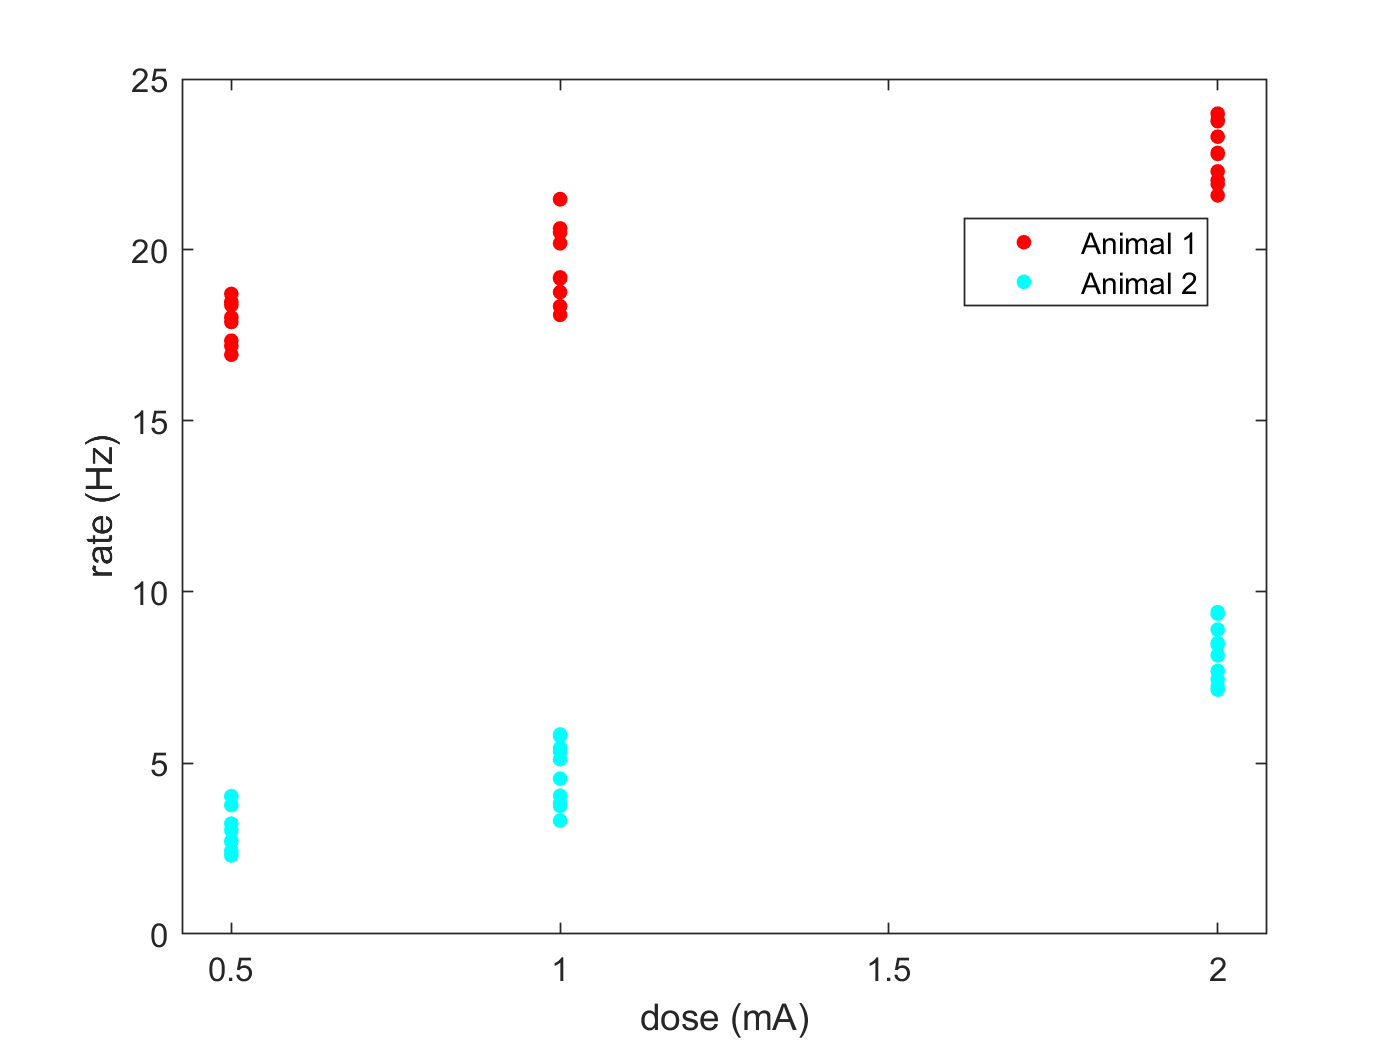

% Add 4 Hz extra spikes to all neurons recorded in animal 1
% Note the use of categorical(1)
rate(animal==categorical(1)) = rate(animal==categorical(1)) + 15;
T=table(rate,animal,dose);

figure;
gscatter(T.dose,T.rate,T.animal)
xlabel 'dose (mA)'
ylabel 'rate (Hz)'
legend('Animal 1','Animal 2')

It looks like there is an effect of current dose, but a linear model with fixed-effects only finds only a marginally significant effect of dose. By construction, we know that the effect of dose was the same in both animals, but just because animal 1 has an overall higher mean firing rate, this effect is washed out in the analysis. 

lmm = fitlme(T,'rate~dose')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations              60
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rate ~ 1 + dose

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    417.82    424.11    -205.91          411.82  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF    pValue       Lower      Upper 
    {'(Intercept)'}         8.877      2.0499    4.3305    58    5.969e-05     4.7737     12.98
    {'dose'       }        3.3348      1.5496    2.1521    58     0.035567    0.23296    6.4366

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        7.4851      6.2589    8.9517


Another way to look at the failure of the model is by compariing its predictions with the actual data:

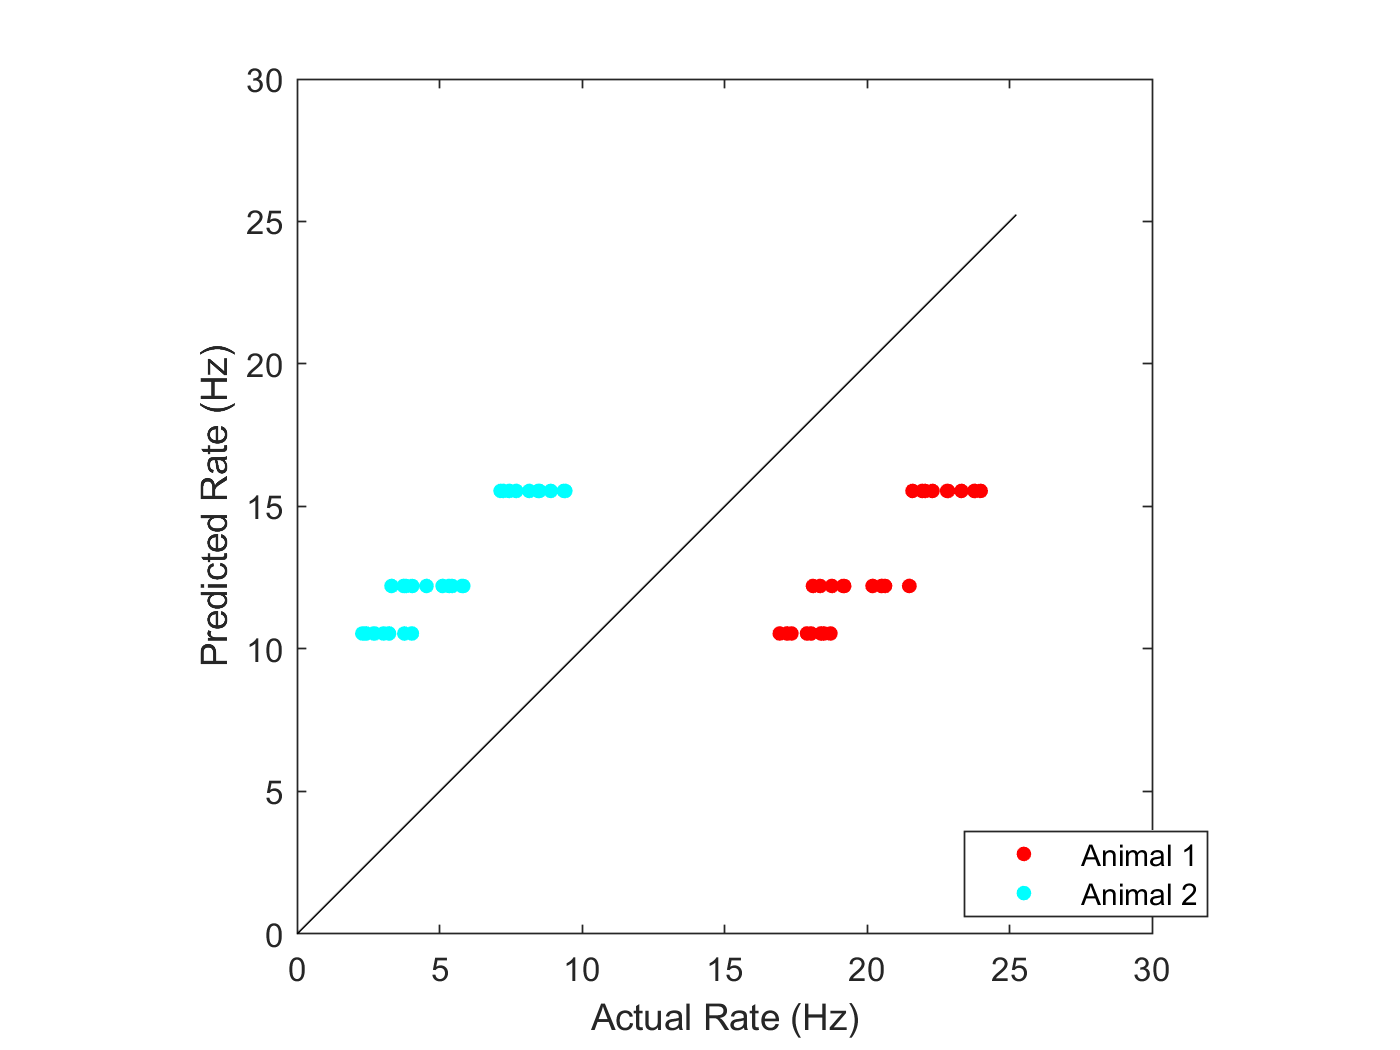

figure;
predicted = predict(lmm,T); % Calculate model prediction for each data point
gscatter(T.rate,predicted,T.animal);
hold on
plot(xlim,xlim,'k')
xlabel 'Actual Rate (Hz)'
ylabel 'Predicted Rate (Hz)'
hold on
plot(xlim,xlim,'k')
axis equal; axis square; 

legend('Animal 1','Animal 2')

Clearly the model is not doing well; none of the data points are near the unity line. 

To handle this, we extend the model with a parameter (a random effect) that captures the mean firing rate per animal. In Wilkinson notation this is specified as (1|animal), which you should read as 'fit a separate intercept (1) for each animal': 

lmm = fitlme(T,'rate~dose + (1|animal)')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations              60
    Fixed effects coefficients           2
    Random effects coefficients          2
    Covariance parameters                2

Formula:
    rate ~ 1 + dose + (1 | animal)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    175.37    183.75    -83.687          167.37  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF    pValue        Lower      Upper 
    {'(Intercept)'}         8.877       5.2629    1.6867    58      0.097034    -1.6579    19.412
    {'dose'       }        3.3348      0.17768    18.768    58    2.5786e-26     2.9791    3.6904

Random effects covariance parameters (95% CIs):
Group: animal (2 Levels)
    Name1                  Name2                  Type           Estimate    Lower     U

The model has the same fixed-effect coefficients, but 2 additional random effects (one intercept for each of the 2 animals). The estimate of the fixed-effect of dose is the same as in the model without random effects (3.3 Hz/mA), but the confidence interval is much narrower, and the p-value is much lower. The model is clearly better; most points in the figure are near the unity line.

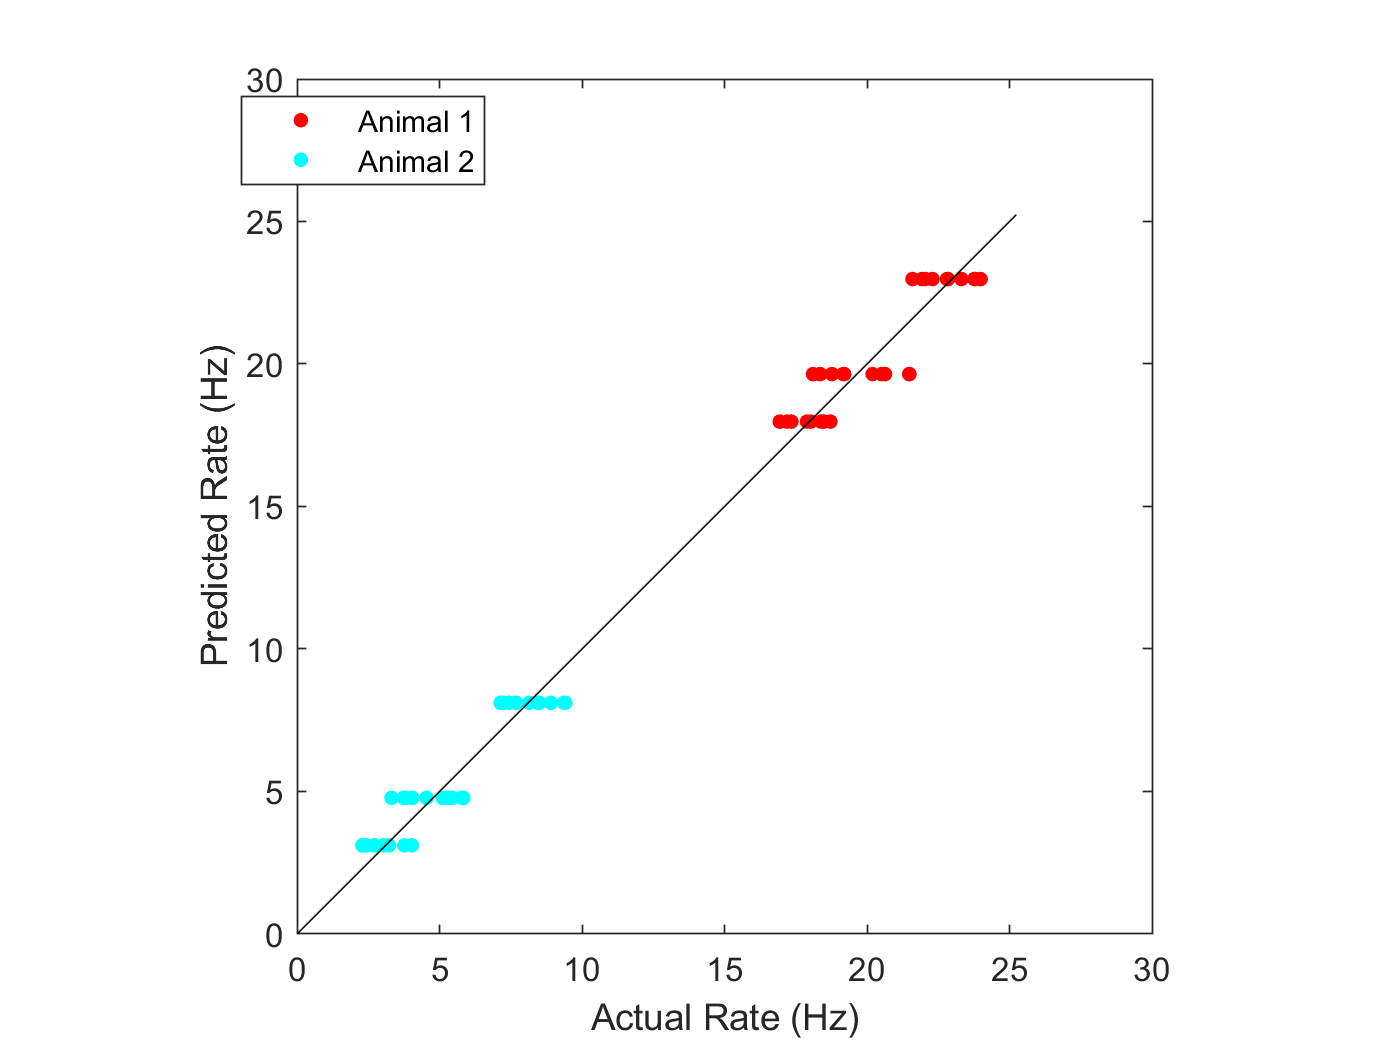

figure;
predicted = predict(lmm,T); % Calculate model prediction for each data point
gscatter(T.rate,predicted,T.animal);
hold on
plot(xlim,xlim,'k')
xlabel 'Actual Rate (Hz)'
ylabel 'Predicted Rate (Hz)'
hold on
plot(xlim,xlim,'k')
axis equal; axis square; 
legend('Animal 1','Animal 2')

anova(lmm)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        2.8449    1      58       0.097034
    {'dose'       }        352.25    1      58     2.5786e-26


When reporting the result of this kind of mixed effect model, you should write something like : 

*We used a linear mixed effects model to test the hypothesis that current dose affects the mean firing rate. *

*Dose was treated as a fixed effect, and we included an intercept per animal as a random effect. In Wilkinson notation: rate ~dose + (1|animal).*

*The fixed-effect of dose was 3.3 Hz/mA with CI: [2.98; 3.69] and it was significantly different from zero (F(1,58), p=2.58e-26)*

### Random Slope Effects

Most often, you include random effects for intercepts to allow your subjects (or other groupings in your measurements) to have different mean values. However, it can also be reasonable to include random effects for other model parameters. For instance, in the current example, it would not be unreasonable to hypothesize that the effect of the current is not identical in each animal. It is conceivable that one animal has a steep slope, while another has a more shallow slope. A linear model can capture this by fitting one slope for all animals together (the fixed effect), as well as slopes for each animal (the random effects). In the behavioral training/reaction tiem example this model would represent a situtation where everyone improves due to training (a non-zero fixed-effect) , but some improve more than others. 

Simulated data may help to clarify:

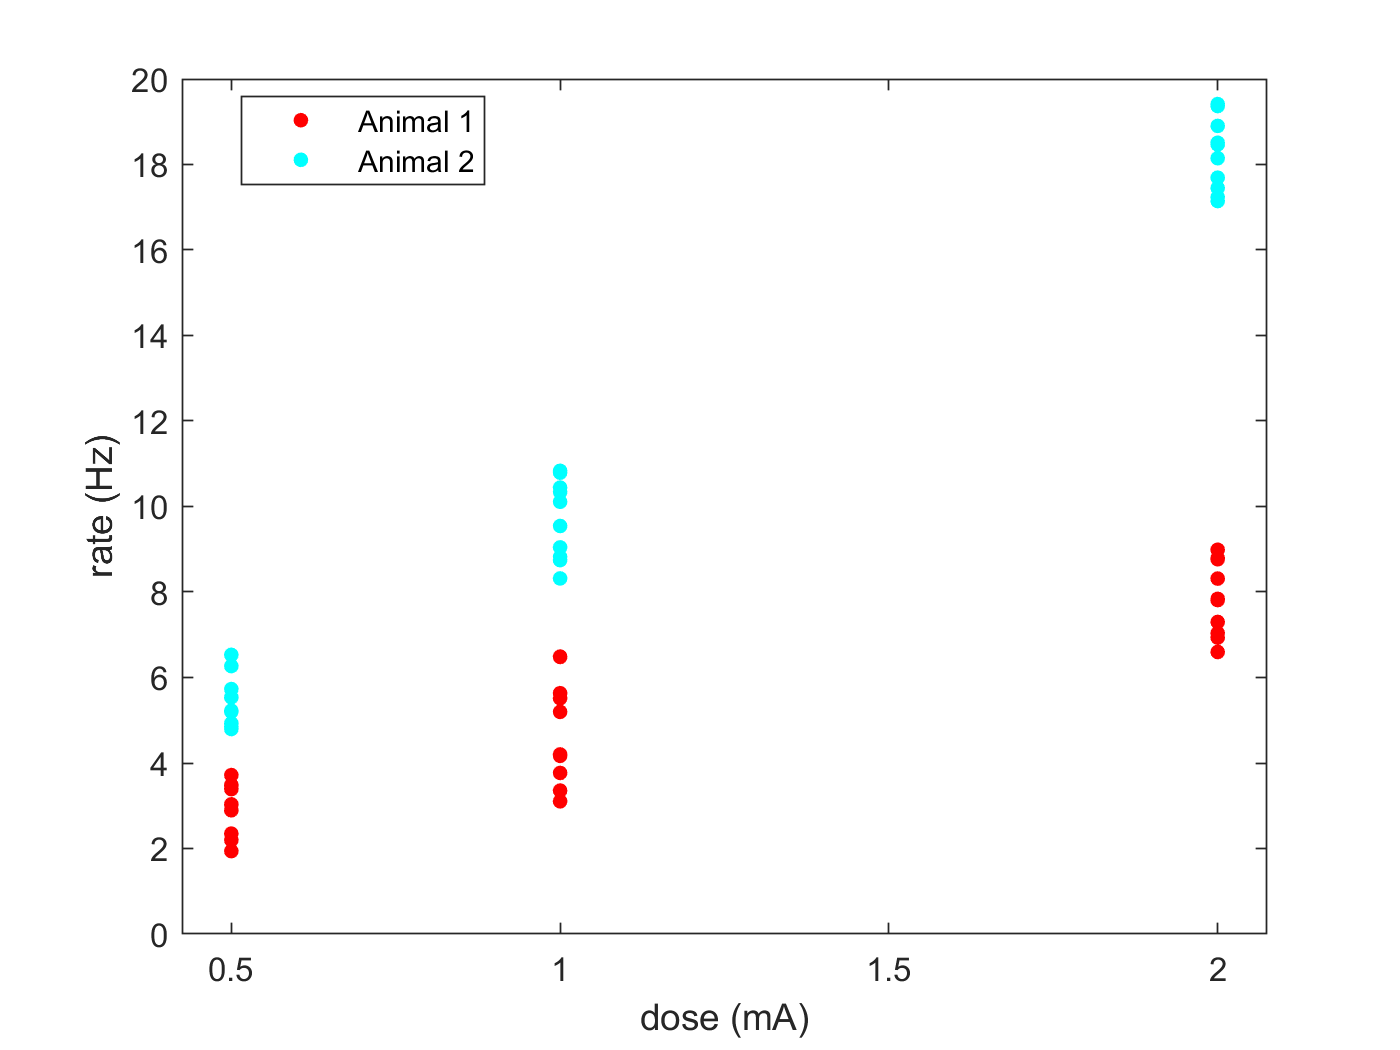

% Setup independent variables
rng(1230,'twister'); % Keep random numbers repeatable between runs
currentDose     = [0.5 1 2]; % mA
nrDoses         = numel(currentDose);
nrAnimals       = 2;
nrNeurons = 10;
meanRate = [3 5 8];
rate = repmat(meanRate,[nrAnimals*nrNeurons 1]);
rate = rate(:) +randn([numel(rate) 1]);
animal    = repmat((1:nrAnimals)',[nrNeurons nrDoses ]);
animal     = categorical(animal(:)); % Force the animal variable to be categorical
dose    = repmat(currentDose,[nrNeurons*nrAnimals 1]);
dose = dose(:);
T=table(rate,animal,dose);


isAnimal2 = animal==categorical(2);
T.rate(isAnimal2) = T.rate(isAnimal2)+T.dose(isAnimal2)*5; % 
figure;
gscatter(T.dose,T.rate,T.animal)
xlabel 'dose (mA)'
ylabel 'rate (Hz)'
legend('Animal 1','Animal 2')

This figure shows that the animals now not only have a different overall mean rate, the current dose affects animal 2 more than animal 1

To allow for this in the model, we add a random-effect of dose for each animal :

lmm = fitlme(T,'rate~dose+(1+dose | animal)')

lmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations              60
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4

Formula:
    rate ~ 1 + dose + (1 + dose | animal)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    175.73    188.29    -81.864          163.73  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF    pValue        Lower      Upper 
    {'(Intercept)'}         1.377      0.24171    5.6968    58    4.2846e-07    0.89315    1.8608
    {'dose'       }        5.8348       1.8641    3.1301    58     0.0027354     2.1034    9.5662

Random effects covariance parameters (95% CIs):
Group: animal (2 Levels)
    Name1                  Name2                  Type            Estimate    Low

Compare this with a model that does not include a random effect for dose:

lmmFixed= fitlme(T,'rate~dose')

lmmFixed = Linear mixed-effects model fit by ML

Model information:
    Number of observations              60
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rate ~ 1 + dose

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    326.68    332.96    -160.34          320.68  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF    pValue        Lower      Upper 
    {'(Intercept)'}         1.377      0.95913    1.4357    58       0.15646    -0.5429    3.2969
    {'dose'       }        5.8348      0.72503    8.0476    58    5.0968e-11     4.3835    7.2861

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        3.5022      2.9285    4.1884


So, the fixed-effects model estimated the same fixed-effect for dose, but the model is actually much worse. We can show this graphically:

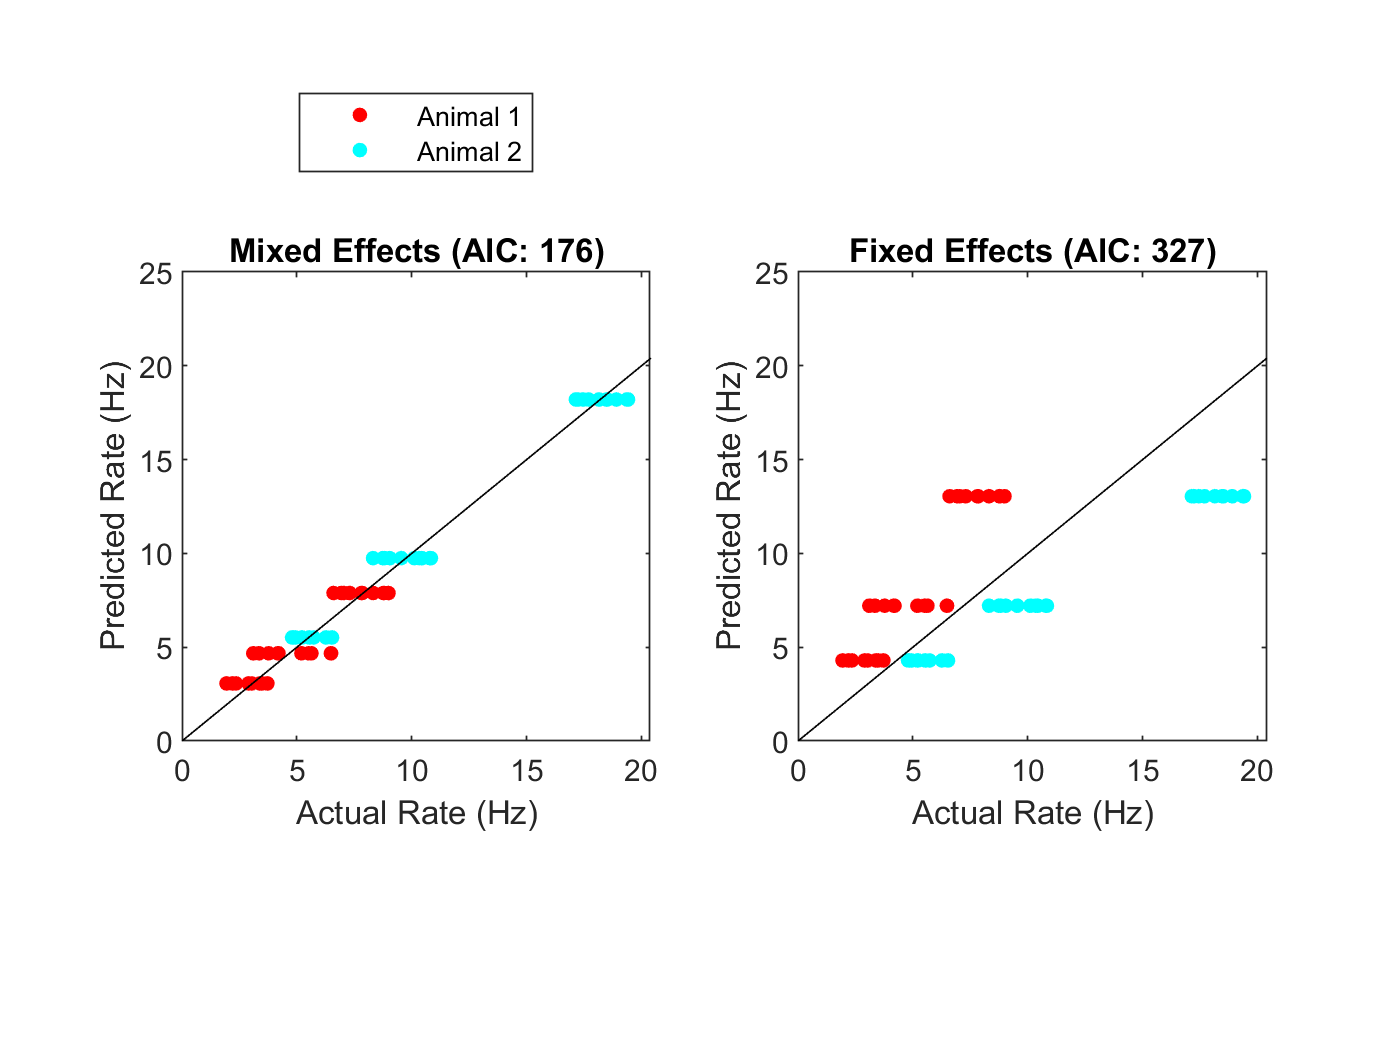

figure;
subplot(1,2,1)
predicted = predict(lmm,T); % Calculate model prediction for each data point
gscatter(T.rate,predicted,T.animal);
hold on
plot(xlim,xlim,'k')
xlabel 'Actual Rate (Hz)'
ylabel 'Predicted Rate (Hz)'
hold on
plot(xlim,xlim,'k')
axis equal; axis square; 
legend('Animal 1','Animal 2')
title (sprintf('Mixed Effects (AIC: %3.3g)',lmm.ModelCriterion.AIC))

subplot(1,2,2)
predicted = predict(lmmFixed,T); % Calculate model prediction for each data point
gscatter(T.rate,predicted,T.animal);
hold on
plot(xlim,xlim,'k')
xlabel 'Actual Rate (Hz)'
ylabel 'Predicted Rate (Hz)'
title (sprintf('Fixed Effects (AIC: %3.3g)',lmmFixed.ModelCriterion.AIC))
hold on
plot(xlim,xlim,'k')
axis equal; axis square; 
legend off

Wit few data points near the unity line, the fixed effects model is clearly much poorer than the mixed effects model. We quantify this with the AIC (Akaike Information Criterion) or BIC (Bayesian Information Criterion from Model Fit Statistics. Both AIC and BIC start by calculating the log-likelihood of the model. This uses equations  such as Equation 1 in the section on Normality, above. Graphically, you can get an idea of the log-likelihood by comparing predicted values and actual values (in the figure above this is how close the data are to the unity line).  If all predictions are on the unity line, the log-likelihood is zero, every data point that is away from the unity line makes the log-likelihood more negative. 

We can convert the log-likelihood to something called the deviance by simply multiplying it by -2. Small deviances correspond to good fits, while large deviances represent poor model fits.  However, comparing two models based on the deviance can be tricky because adding parameters to the model always makes it fit the data better (a model with as many free parameters as there are measurements in the data will be a perfect model, but also perfectly useless). AIC and BIC address this problem by correcting the deviance for the number of free parameters. AIC adds 2 for every free parameter: $AIC = deviance + 2*k$, with $k$ the number of free parameters, while BIC also takes the number of data points $(n)$into account: $BIC =deviance+k*ln(n)$. For most practicaly purposes you should just pick AIC or BIC and stick with them. If two models differ by more than 10 (AIC or BIC), then the model with the lower value is substantially better. Differences of less than 3 are not meaningful, and the range in between is a grey zone. In the example $\Delta AIC$~ 50 so the mixed effects model is much better (as confirmed by the graph above).

Although it is preferable to determine the inclusion of random-effects a-priori (i.e. is it a-priori reasonable to expect the same effect across all animals/subjects?), post-hoc analyses using AIC can help to decide whether the inclusion of random effects improves the model or not. 

For instance, here are 5 animals with similar current dose effects:

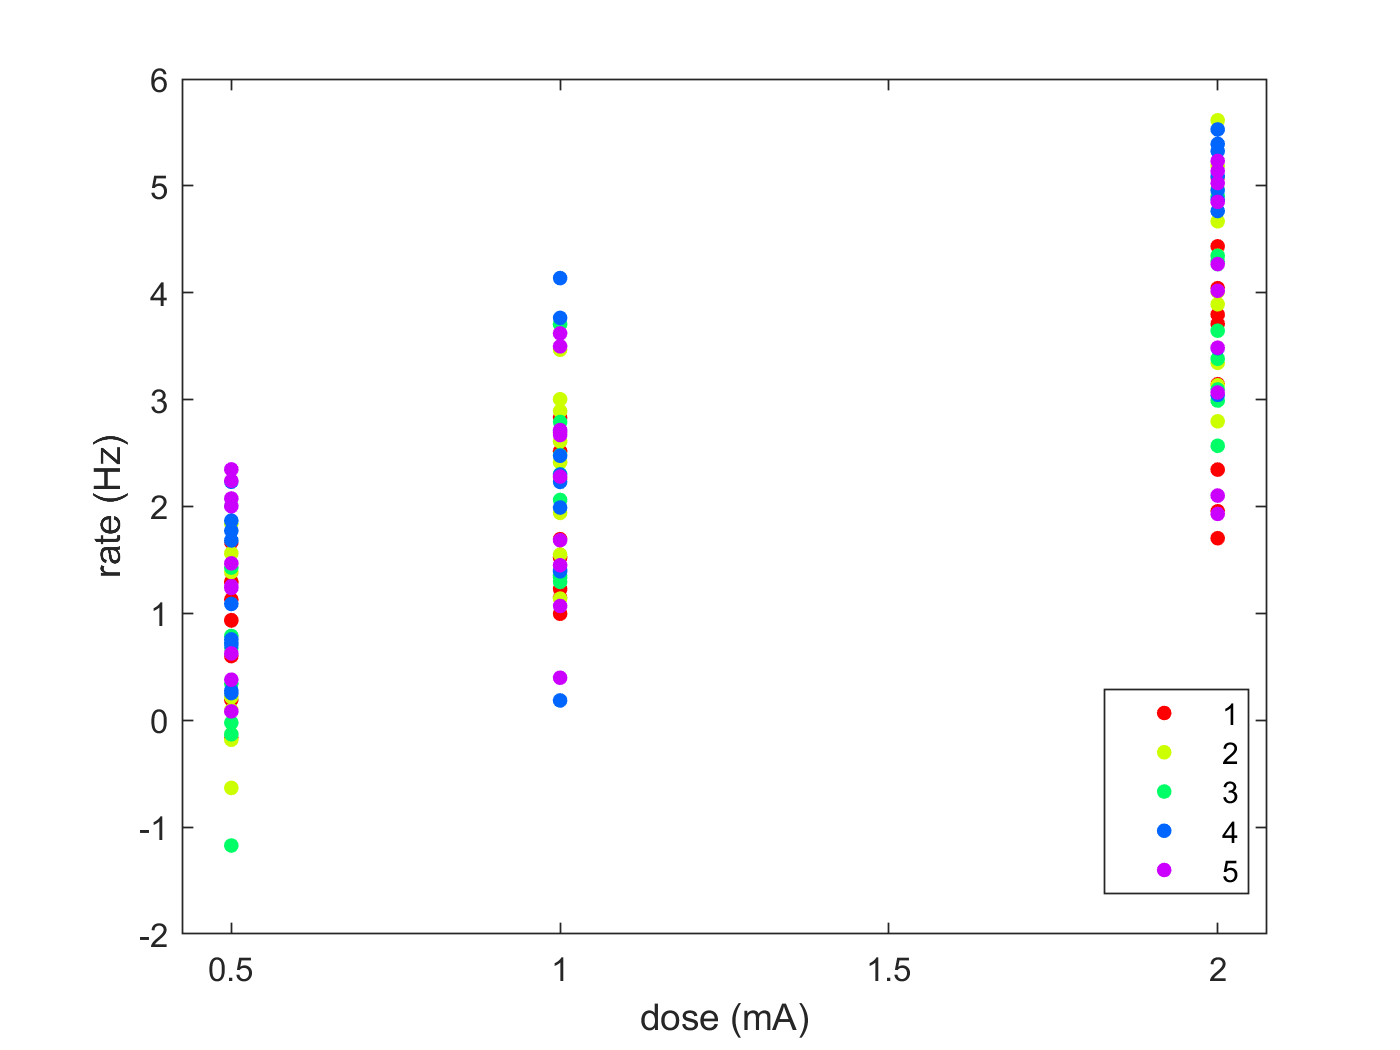

% Setup independent variables
rng(1230,'twister'); % Keep random numbers repeatable between runs
currentDose     = [0.5 1 2]; % mA
doseEffectPerAnimal = [1.8 2.1 1.9 2.2 2];
nrDoses         = numel(currentDose);
nrAnimals       = numel(doseEffectPerAnimal);
nrNeurons = 10;
rate =[];
animal=[];
dose =[];
for i=1:nrAnimals
    for j = 1:nrDoses
    rate = [rate; currentDose(j)*doseEffectPerAnimal(i) + randn(nrNeurons,1)]; %#ok<AGROW> 
    animal = [animal;i*ones(nrNeurons,1)];%#ok<AGROW> 
    dose = [dose;currentDose(j)*ones(nrNeurons,1)];  %#ok<AGROW> 
    end
end
T=table(rate,animal,dose);
figure;clf
gscatter(T.dose,T.rate,T.animal)
xlabel 'dose (mA)'
ylabel 'rate (Hz)'

In this case, the fixed effects model does quite well, and its AIC is even somewhat smaller than the AIC of the mixed model. Hence there is little reason to include the dose slopes as random effects.

    
lmmFixed = fitlme(T,'rate~dose');
lmmMixed = fitlme(T,'rate~dose+(dose|animal)');
lmmFixed.ModelCriterion.AIC

ans = 407.4021

lmmMixed.ModelCriterion.AIC

ans = 411.1683

## N-way ANOVAs and Interactions

The examples only showed examples with one independent variable - corresponding to one-way analysis of variance in the traditional framework. LMM, however, can handle any number of factors, levels, and interactions. Most models can be specified with the Wilkinson formulas, by just adding variables on the right side of the ~. For instance:

`performance ~ age*gender + (1|subject)`

Specifies a model of performance with fixed effects of age, gender, and their interaction, plus a random intercept for each subject. 

If a drug is involved, we could extend this to:

`performance ~ age*gender + drug + age:drug + (1|subject)`

which will model an effect of drug, plus an effect of drug that interacts with age.

See `help fitlme `for a full list of operators that you can use in Wilkinson notation. 